## Instituto Tecnológico de Estudio Superiores de Monterrey Campus Guadalajara

## Agricultura de Precisión 

El siguiente escrito presenta el clasificador de imagenes para la distincion entre objetos deseados o no, en este caso se presenta la segmentacion entre hojas y flores, las diferentes categorias pueden ser modificadas, y con ello el conjunto de datos que se exponen al proceso de entrenamiento del clasificador.

el siguiente apartado presenta la manera de definir la carpeta donde se encuentra el conjunto de datos, para este caso son imagenes.

rootFolder = '/home/wagner/Documents/semanai/proyecto/final/data';
categories = {'flores','hojas'};
%data mgmt
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');

Define algunas etiquetas para definir las categorias a analizar.

%images images number by category
tbl = countEachLabel(imds)

tbl = 2×2 table
    Label     Count
    ______    _____

    flores     573 
    hojas      224 


Se realiza el previo entrenamiento, donde se define que parte del dataset sera utilizado para entrenamiento y pruebas.

%training and validation
minSetCount = min(tbl{:,2}); % determine the smallest amount of images in a category
% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');
% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 2×2 table
    Label     Count
    ______    _____

    flores     224 
    hojas      224 


Se asigna un porcentaje de 30% del conjunto de datos para que sean utilizados en la estaba de prueba del clasificador

%select percent of the set to be part of the training data the other half
%for testing
[trainingSet, validationSet] = splitEachLabel(imds, 0.3, 'randomize');

Se definen las primeras instancias de las dos categorias existentes

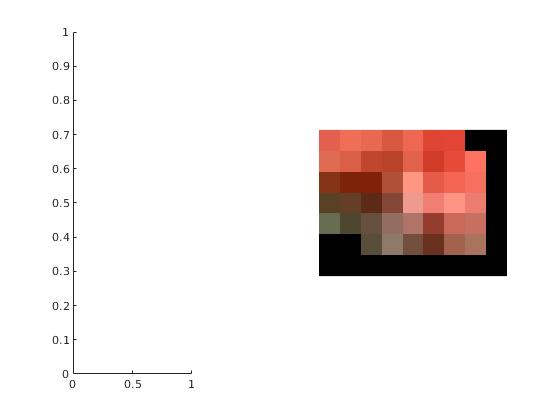

% Find the first instance of an image for each category
flores = find(trainingSet.Labels == 'flores', 1);
hojas = find(trainingSet.Labels == 'hojas', 1);

% figure
subplot(1,3,1);
subplot(1,2,2);
imshow(readimage(trainingSet,flores))

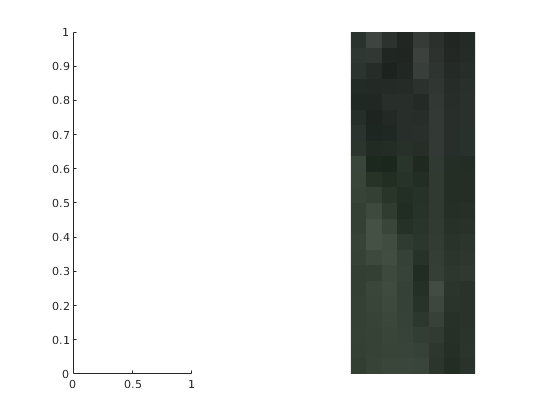

imshow(readimage(trainingSet,hojas))

%subplot(1,3,n);

Se define un vocabulario el cual es parte del conjunto de pruebas

%vocabulary & ffeatures
bag = bagOfFeatures(trainingSet);


Creating Bag-Of-Features.
-------------------------
* Image category 1: flores
* Image category 2: hojas
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 134 images...done. Extracted 3562 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 2 has the least number of strongest features: 531.
** Using the strongest 531 features from each of the other image categories.

* Using K-Means clustering to create a 500 word visual vocabulary.
* Number of features          : 1062
* Number of clusters (K)      : 500

* Initializing cluster centers...100.00%.
* Clustering...completed 8/100 iterations (~0.04 seconds/iteration)...converged in 8 iterations.

* Finished creating Bag-Of-Features



Se muestras las diferentes apariciones del vocabulario anterior, donde destaca las repeticiones de cada parte del diccionario

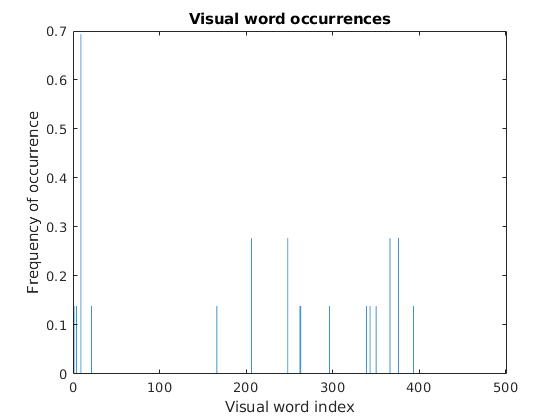

%ocurrencies
img = readimage(imds, 1);
featureVector = encode(bag, img);

% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

Se define parte del clasificador, donde se utiliza el vocabulario anteriormente presentado

%classifier statistics
categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);


Training an image category classifier for 2 categories.
--------------------------------------------------------
* Category 1: flores
* Category 2: hojas

* Encoding features for 134 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



Se crea una matriz de confusion con los datos del conjunto de pruebas y las categorias presentadas por el clasificador

%classifier performance
confMatrix = evaluate(categoryClassifier, trainingSet);


Evaluating image category classifier for 2 categories.
-------------------------------------------------------

* Category 1: flores
* Category 2: hojas

* Evaluating 134 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


               PREDICTED
KNOWN     | flores   hojas   
-----------------------------
flores    | 1.00     0.00    
hojas     | 0.00     1.00    

* Average Accuracy is 1.00.



se define la matrix con el conjunto de validacion

%validation set
confMatrix = evaluate(categoryClassifier, validationSet);


Evaluating image category classifier for 2 categories.
-------------------------------------------------------

* Category 1: flores
* Category 2: hojas

* Evaluating 314 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


               PREDICTED
KNOWN     | flores   hojas   
-----------------------------
flores    | 0.94     0.06    
hojas     | 0.03     0.97    

* Average Accuracy is 0.96.



Calcula el promedio de exactitud

% Compute average accuracy
mean(diag(confMatrix));

El clasificador ya esta entrenado, por lo tanto se utilizan imagenes del conjunto de prueba.

Finalmente se obtiene el resultado donde la imagen usada para la prueba obtiene tu etiqueda otorgada por el clasificador.

% Trained classifier with the test images
img = imread(fullfile(rootFolder, 'flores', 'sample_260.png'));
[labelIdx, scores] = predict(categoryClassifier, img);

% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'flores'}
